# Problem 1

Student 1: Laura Train García

Student 2: Cristina Sánchez Martín

Data of the problem:

clear;clc; close all;


% data for launch
muE = 398600;                   % mu Earth [km^3/s^2]
Rearth = 6371;                  % mean radius of Earth[km]
h = 2000;                       % altitude [km]

% data for the final point
a2 = 30000;                      % semi-major axis [km]
e2 = 0.1;                        % eccentricity
Omega2 = deg2rad(210);           % RAAN [rad]
inc2 = deg2rad(25);              % inclination [rad]
omega2 = deg2rad(36);            % argument of the periapsis [rad]

## Lambert example

The following example tries to test the Lambert algorithm for the simplest case one can verify, a Hohmann transfer. The verification will consist of solving the problem using both methods separately and then asserting the result is the same. The transfer will take place at the following 

a = 30,000 km

e = 0

Ω = 210º

i = 25º

ω = 25º

Note that e = 0 because a Hohmann transfer implies two circular orbits.

Let us solve the Hohmann transfer first.

% data for the initial point
a1 = Rearth + h;                     % semi-major axis [km]
e1 = 0;                              % eccentricity
Omega1 = deg2rad(210);               % RAAN [rad]
inc1 = deg2rad(25);                  % inclination [rad]
omega1 = deg2rad(36);                % argument of the periapsis [rad]
theta1 = 0;                          % true anomaly [rad]

% compute initial position and initial orbit velocity
[r1, v0] = coe2rv(muE, a1, e1, Omega1, inc1, omega1, theta1);

% ECI reference frame. i0 coincides with the vernal equinox
i0 = [1; 0; 0];
j0 = [0; 1; 0];
k0 = [0; 0; 1];

% compute velocities
[v1_HT, v2_HT, dV_HT] = HT(muE, a1, a2);

fprintf("Hohmann transfer results \n")

Hohmann transfer results 


fprintf("The initial velocity of the transfer is %.3f m/s \n", v1_HT)

The initial velocity of the transfer is 8.629 m/s 


fprintf("The final velocity of the transfer is %.3f m/s \n", v2_HT)

The final velocity of the transfer is 2.408 m/s 


fprintf("The total deltaV is %.3f m/s \n\n", dV_HT)

The total deltaV is 2.966 m/s 



One of the inputs for the Lambert problem is the transfer time. Let's compute the transfer time for the Hohmann transfer.

% final position
theta2 = deg2rad(180);               % true anomaly [rad]
e2_circular = 0;

[r2, vF] = coe2rv(muE, a2, e2_circular, Omega2, inc2, omega2, theta2);

% parameters of the orbit
eHT = (a2 - a1)/(a2 + a1);
aHT = (a2 + a1)/2;

% compute eccentric anomaly
E1 = theta2E(theta1, eHT);
E2 = theta2E(theta2, eHT);

% compute mean anomaly
M1 = E2M(E1, eHT);
M2 = E2M(E2, eHT);

% compute time from the periapsis
t1 = M2dt(M1, muE, aHT);
t2 = M2dt(M2, muE, aHT);
    
dT_HT = t2 - t1;

% get ellipse coordinates for initial and final orbits plot
r1_coords = ellipse_coords(muE, a1, e1, Omega1, inc1, omega1);
r2_coords = ellipse_coords(muE, a2, e2_circular, Omega2, inc2, omega2);

% solve short arc Lambert solution
tf = dT_HT;
k_short = cross(r1,v0)/norm(cross(r1,v0));

% solve Lambert algorithm
[v1, v2, g, f] = Lambert(r1, r2, k_short, tf, muE);

% deltaV of the first firing
DV1 = norm(v1-v0);

% deltaV of the second firing
DV2 = norm(vF-v2);

% total deltaV
DV = abs(DV1) + abs(DV2);

fprintf("The initial velocity of the transfer is %.3f m/s \n", norm(v1))

The initial velocity of the transfer is 8.629 m/s 


fprintf("The final velocity of the transfer is %.3f m/s \n", norm(v2))

The final velocity of the transfer is 2.408 m/s 


fprintf("The total deltaV is %.3f m/s \n\n", DV)

The total deltaV is 2.966 m/s 



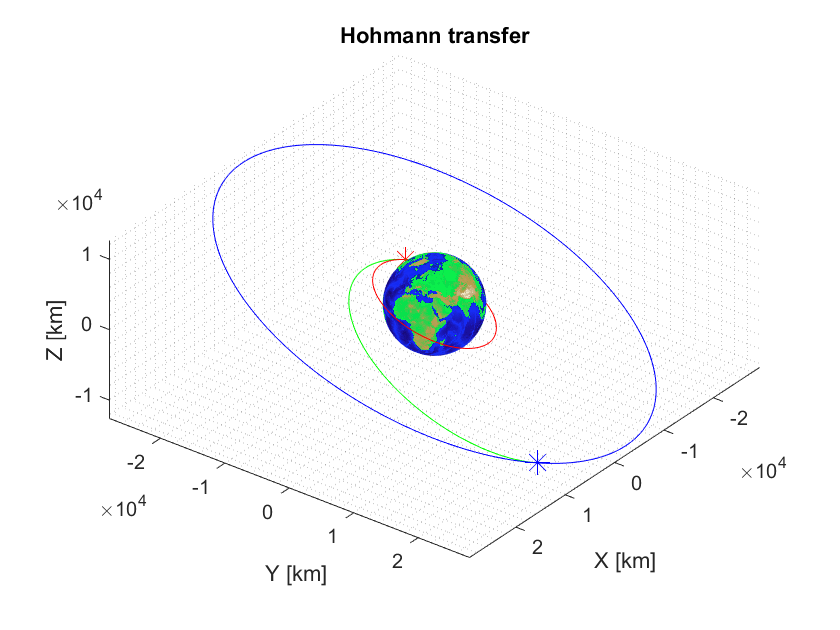

% transfer orbit
rt_coords = ellipse_coords(muE, aHT, eHT, Omega1, inc1, omega1);

% plot initial and final points and orbits
figure(2)
earth_sphere('km')
hold on
plot3(r1(1), r1(2), r1(3), 'r*', r2(1), r2(2), r2(3), 'b*', 'MarkerSize',12)
hold on 
plot3(r1_coords(1,:), r1_coords(2,:), r1_coords(3,:), 'r', r2_coords(1,:), r2_coords(2,:), r2_coords(3,:), 'b', rt_coords(1,1:(end/2)), rt_coords(2,1:(end/2)), rt_coords(3,1:(end/2)), 'g')
title('Hohmann transfer')
hold off
grid minor
axis equal

## Initial exploration

% % chord vector
% c = r2 - r1;
% 
% % eccenticity projection along ic
% eF = (norm(r2) - norm(r1))/norm(c);
% 
% eTfinal = sqrt(1 - eF^2);
%     
% eT = linspace(-eTfinal + 0.01, eTfinal - 0.01, 100);
% for i = 1:length(eT)
%     res(i) = g(eT(i));
% end
% 
% figure(1)
% plot(eT, res, 'r*')
 

tau = orbital_period(a2, muE);
N = 10;
theta1_vec = linspace(0,2*pi,N);
theta2_vec = linspace(0,2*pi,N);
tf_vec = linspace(0,tau,N);
[theta1,theta2,tf] = meshgrid(theta1_vec, theta2_vec, tf_vec);

DV = zeros(N,N,N);
for i = 1:N
    for j = 1:N
        for k = 1:N
            DV(i,j,k) = cost(theta1(i,j,k),theta2(i,j,k),tf(i,j,k));
        end
    end
end

Error: bisection method requires having f(xL) and f(xR) of different sign
No elliptic transfer is possible for the given time of flight
Error: bisection method requires having f(xL) and f(xR) of different sign
No elliptic transfer is possible for the given time of flight
Error: bisection method requires having f(xL) and f(xR) of different sign
No elliptic transfer is possible for the given time of flight
Error: bisection method requires having f(xL) and f(xR) of different sign
No elliptic transfer is possible for the given time of flight
Error: bisection method requires having f(xL) and f(xR) of different sign
No elliptic transfer is possible for the given time of flight
Error: bisection method requires having f(xL) and f(xR) of different sign
No elliptic transfer is possible for the given time of flight
Error: bisection method requires having f(xL) and f(xR) of different sign
No elliptic transfer is possible for the given time of flight
Error: bisection method requires having f(xL) an

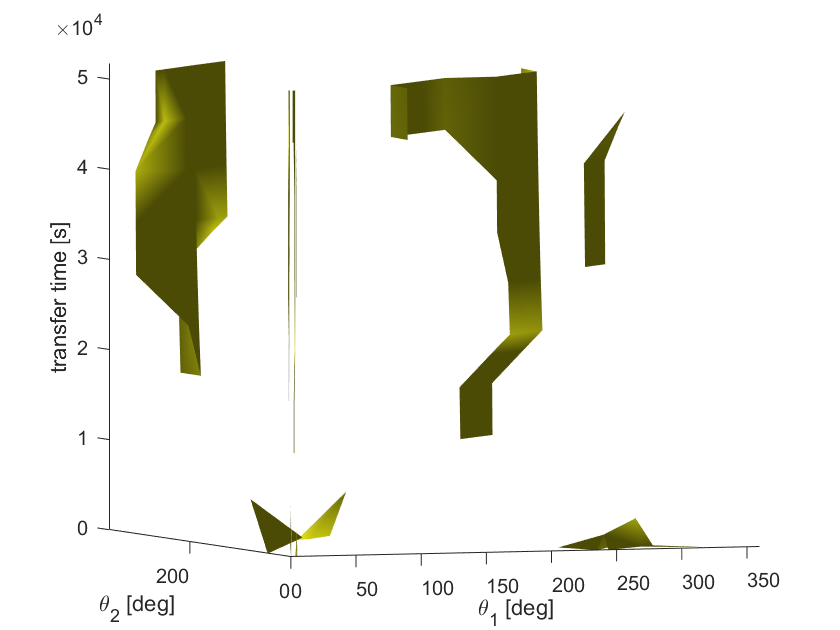

figure(3)
f1 = isosurface(rad2deg(theta1),rad2deg(theta2),tf,DV, 11)

xlabel('\theta_1 [deg]')
xlim([0, 360])
ylabel('\theta_2 [deg]')
ylim([0, 360])
zlabel('transfer time [s]')
zlim([0, tf(end)])

## Optimization of the transfer

Explanation of what you do, why and how...

% ...

## Discussion

(Complete your report)